Train ELM from human demonstration of curve tracing

clc; clear; close all;
tic;
pathname = [pwd '/datafiles/'];
file_list = dir([pathname '*.fig8.hman.mat']);

load('training_settings.mat');
cm = 1/100;
mm = 1/1000;
clean_outliers = 0;

## Who's who

adele - subject1

agnes - subject2

aniket - subject3

bernardo - subject4

cuishuai - subject5

domenico - subject6

harsha_v4 - subject7

juhi - subject8

kieran - subject9

sreekanth - subject10


for j_files = 1:length(file_list)
    filename = file_list(j_files).name;
    subject_id = strsplit(filename,'.fig8.hman.mat');
    name = char(subject_id{1});
    disp(name)
    
    %% Defining filenames
    subject_elm_filename = strcat(subject_id{1},'.trained_elm.mat');
    subject_fig1_real_tracing = strcat(subject_id{1},'.FIG_real_tracing');
    subject_fig2_real_power_law = strcat(subject_id{1},'.FIG_real_power_law');

    %% Collecting data from log
    load( strcat(pathname,filename) );

    positions   = data(6:7,:);   % Positions
    velocities  = data(10:11,:); % Velocities
    time        = data(1,:)';    % Time

    %% Pre-processing data
    
    % Zago filtering
    [time_zago, speed_zago, curvature_zago, A_zago, Pt_zago,Vt_zago,At_zago] = f_powerlaw_Zago_v4 (positions, time, sampling_time, cutoff_frequency);
    
    % Segmenting dataset
    range_speed = (speed_zago > mean(speed_zago))';
    min_time = min(time_zago(range_speed)); max_time = max(time_zago(range_speed)); mid_time = (min_time + max_time)/2;
    range_speed = (speed_zago > 0)';
    if j_files == 3
        time_threshold_lower = min_time+15;
    else
        time_threshold_lower = min_time;
    end
    time_threshold_upper = max_time;
    range_segmented = logical ((range_speed .* (time_zago>time_threshold_lower))); range_segmented = logical ((range_segmented .* (time_zago<time_threshold_upper)));

    %% Reparameterisation to ensure training data validity
    
    % Generating geometry
    GEO = f_euclidean_geometry_v3(C);

    %% Reparamaterisation
    SET_pstar = []; SET_err = [];

    Pt = Pt_zago(:,1);
    pstar = 0; % check against demonstration data for starting pstar

    figure

    for Pt = Pt_zago
        pstar = fminbnd(@(p) GEO.dist2(p,Pt), pstar, pstar+pi/2);   %% NOTE [0 pi] is the upper lobe
        SET_pstar = [SET_pstar, pstar];
        SET_err = [SET_err, sqrt( GEO.dist2(pstar, Pt))];
    end

    range_training = range_segmented;
    Pt_training = Pt_zago(:,range_training);
    Vt_training = Vt_zago(:,range_training);
    SET_pstar_training = SET_pstar(range_training);
    
    % Piecewise linear power law regression
    range_power_law = logical (range_training' .* curvature_zago>curvature_threshold);
    x = (curvature_zago(range_power_law));
    y = (speed_zago(range_power_law) );

    if clean_outliers
        ll = 25;
        uu = 75;

        Qu = prctile(x, uu);
        Ql = prctile(x, ll);
        intr_qr = Qu - Ql;

        max_ = Qu+(1.5*intr_qr);
        min_ = Ql-(1.5*intr_qr);
        range_3 = logical(x>min_);
        range_4 = logical(x<max_);
        x = x (range_3&range_4);
        y = y (range_3&range_4);
    end    
    y = log10(y);
    x = log10(x);

    myPWLType = fittype( @(LogV0, LogKc, LogK) ...
        LogV0 + 1/3*(LogKc - LogK).*(1+sign(LogK-LogKc))/2, ...
        'dependent', {'LogV'},...
        'independent', {'LogK'},...
        'coefficients', {'LogV0', 'LogKc'});
    options = fitoptions(myPWLType);
    options.Robust = 'LAR';
    options.StartPoint =  [log10(0.1), log10(5)];
    options.MaxFunEvals = 2000;
    options.MaxIter = 2000;
    options.Display = 'off';
    options.TolX = 1e-15;
    options.TolFun = 1e-15;
    options.Lower = [log10(0.01),log10(1)];
    options.Upper = [log10(1),log10(50)];
    options.Normalize = 'off';

    [Fitting, GoF] = fit( x, y, myPWLType,options);


    VK_par = 10.^coeffvalues(Fitting);
    VK_CI = diff( 10.^ confint(Fitting, 0.95) )/2;
    display(VK_par);

FIGURE : subject_fig1_real_tracing

subject1


VK_par =     0.5143   14.1809


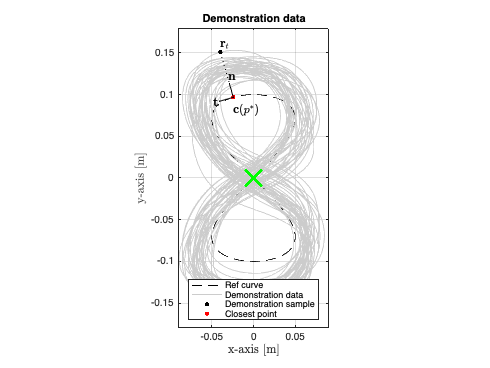

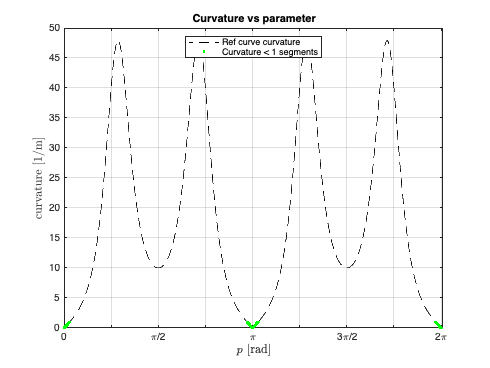

subject10


VK_par =     0.0942   20.5264


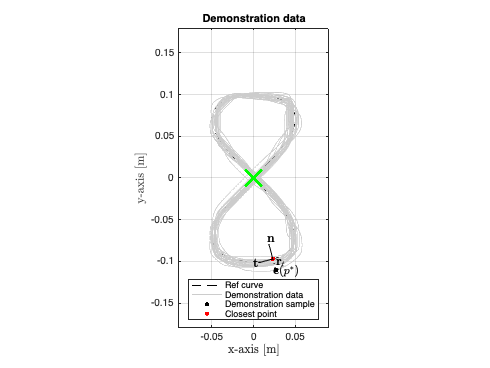

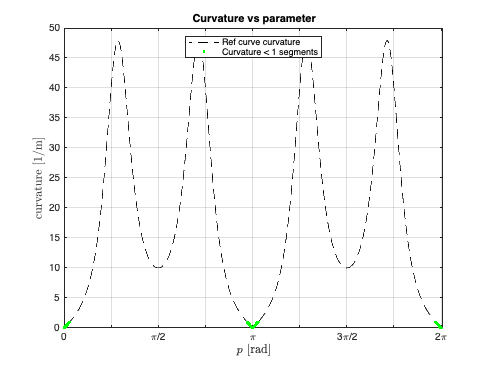

subject2


VK_par =     0.2677   15.1202


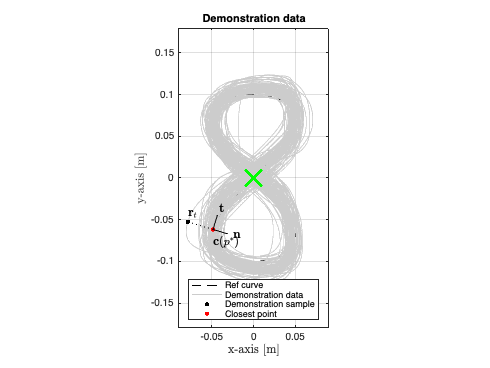

subject3


VK_par =     0.2443   15.5252


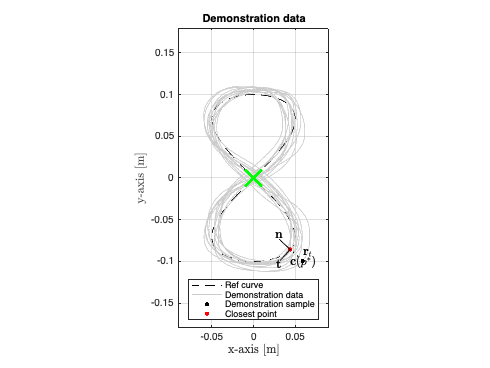

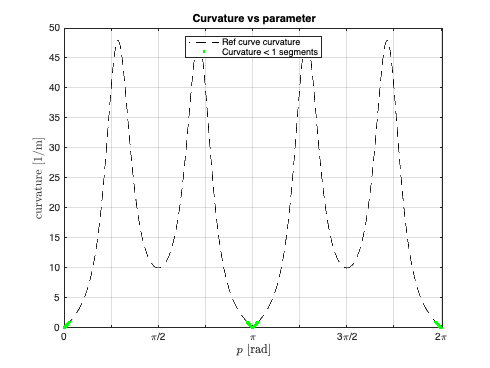

subject4


VK_par =     0.1478   26.4084


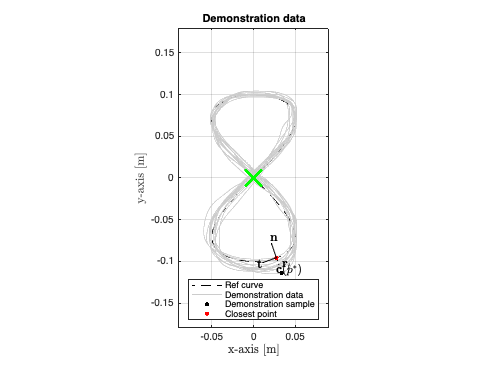

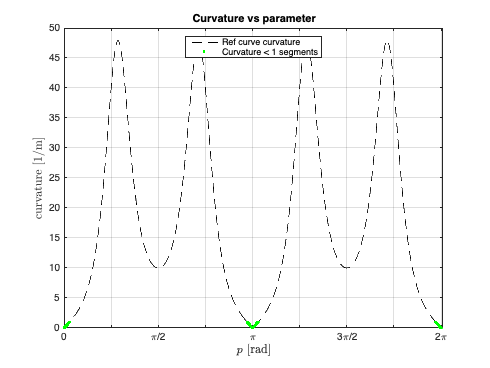

subject5


VK_par =     0.3468   16.1553


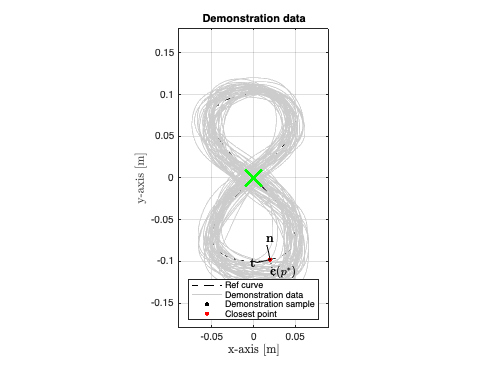

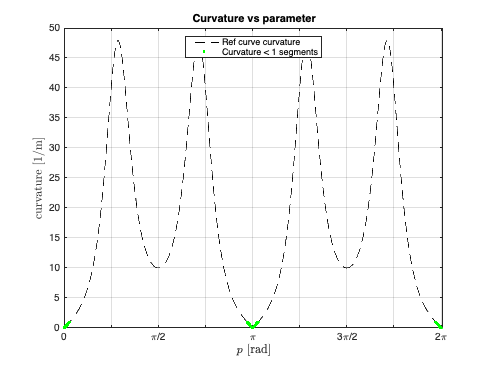

subject6


VK_par =     0.1442   18.8906


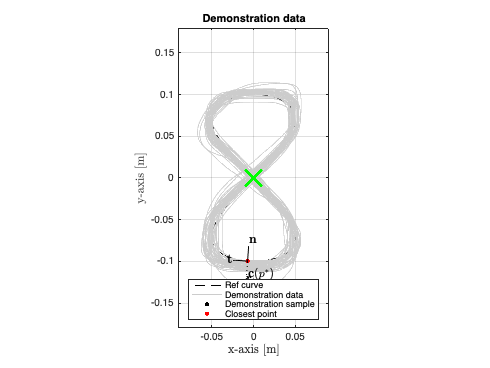

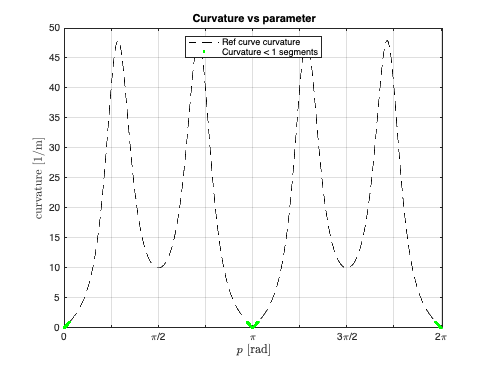

subject7


VK_par =     0.1357   22.8121


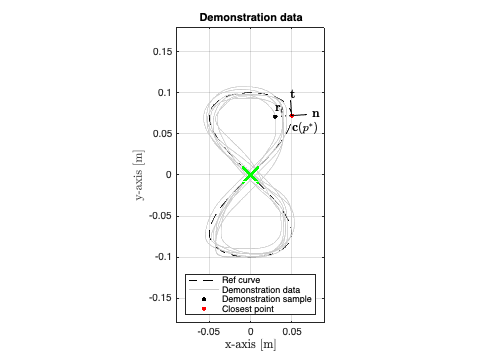

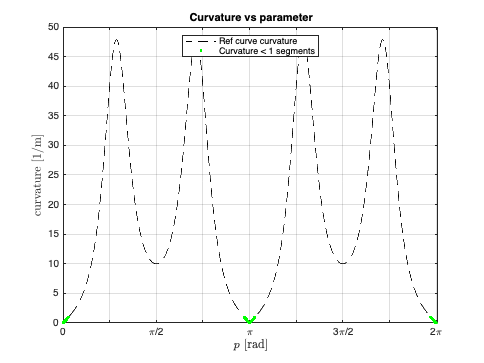

subject8


VK_par =     0.2189   19.4189


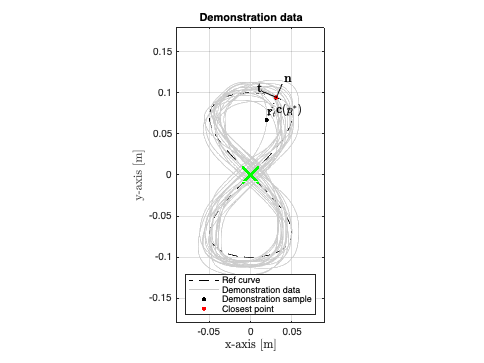

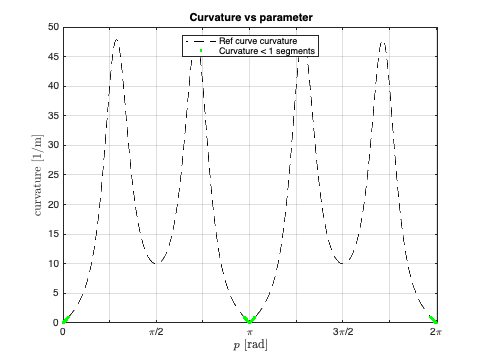

subject9


VK_par =     0.2046   21.1230


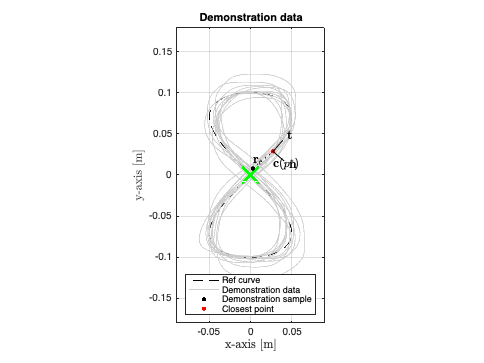

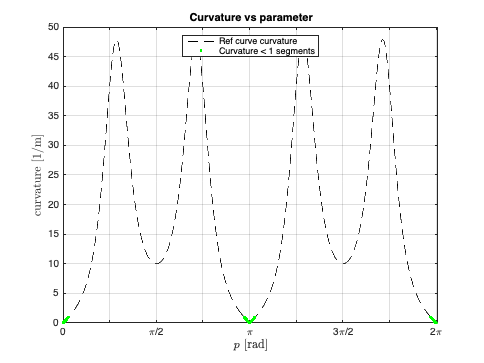

        h_subject_fig1_real_tracing = figure;
        
            ref_curve = my2Dplot(C([0:0.01:2*pi]), '--k'); hold on,
            grid on, axis equal;
            
            xlabel('x-axis [m]','Interpreter','Latex','fontsize',12), ylabel('y-axis [m]','Interpreter','Latex','fontsize',12);
            p = -pi:0.01*sampling_time:2*pi;
            [tmp1, tmp2, C_curv] = f_powerlaw_Zago_v4 (C(p), p, 0.01*sampling_time, cutoff_frequency);
            range_p = logical((p>0)' .* (C_curv>curvature_threshold ));
            range_p_low_curvature = logical((p>0)' .* (C_curv<curvature_threshold ));
            real_tracing_data = my2Dplot(Pt_training,'k'); real_tracing_data.Color = [0.8 0.8 0.8];
            
            low_curvature_sections = graph_opt.my2DscatterXY(C(p(range_p_low_curvature)), '.g'); hold on,

            GEO = f_euclidean_geometry_v3(C);
            
            % Finding extrema for display purposes
            SET_err_training = SET_err(range_training);
            farthest_point_idx = find(SET_err_training==max(SET_err_training));
            farthest_point = Pt_training(:,farthest_point_idx);
            C_pstar_farthest = GEO.C(SET_pstar_training(farthest_point_idx));
            
            h_farthest_point = my2Dplot(farthest_point,'.k'); 
            h_farthest_point.MarkerSize = 10;
            h_C_pstar_farthest = my2Dplot(C_pstar_farthest,'.r'); 
            h_C_pstar_farthest.MarkerSize = 10;
            h_reparam_line = plot([farthest_point(1) C_pstar_farthest(1)],[farthest_point(2) C_pstar_farthest(2)],':k'); 
            text_h_farthest = text(farthest_point(1),farthest_point(2)+0.01,'$\mathbf{r}_t$','Interpreter','Latex','fontsize',12);
            text_h_C_pstar = text(C_pstar_farthest(1),C_pstar_farthest(2)-0.015,'$\mathbf{c}(p^*)$','Interpreter','Latex','fontsize',12);

            
            moving_frame = GEO.MF(SET_pstar_training(farthest_point_idx));

            h_normal = graph_opt.drawVector(C_pstar_farthest,-0.02*moving_frame(1:2,2),'k'); hold on,

            h_tangent = graph_opt.drawVector(C_pstar_farthest,0.02*moving_frame(1:2,1),'k'); hold on,

            tangent = C_pstar_farthest + 0.025*moving_frame(1:2,1);
            normal = C_pstar_farthest - 0.025*moving_frame(1:2,2);

            text_h_tangent = text(tangent(1),tangent(2),'$\mathbf{t}$','Interpreter','Latex','fontsize',12);
            text_h_tangent = text(normal(1),normal(2),'$\mathbf{n}$','Interpreter','Latex','fontsize',12);

            xlim([axis_x_min axis_x_max]);
            ylim([axis_y_min axis_y_max]);
            
            hleglines = [ref_curve real_tracing_data h_farthest_point h_C_pstar_farthest];
            
            % Legend
            hleg = legend(hleglines,'Ref curve','Demonstration data','Demonstration sample','Closest point');
            hleg.Location = 'South';
            title('Demonstration data' )
        
            h_subject_fig1point1_real_tracing = figure;
            h_C = plot(p(p>0), C_curv(p>0), '--k'); grid on, hold on, xlim([0,2.01*pi]);
            h_curvature_thresholded = scatter(p(range_p_low_curvature), C_curv(range_p_low_curvature), '.g');
            xlabel('$p$ [rad]','Interpreter','Latex','fontsize',12), ylabel('curvature [1/m]','Interpreter','Latex','fontsize',12)
            set(gca, 'XTick', pi/4 * (0:8), ...
            'XTickLabel', {'0', '', '\pi/2', '', '\pi', '', '3\pi/2', '', '2\pi'});
            hleglines = [h_C h_curvature_thresholded];
            % Legend
            hleg = legend(hleglines,'Ref curve curvature','Curvature < 1 segments');
            hleg.Location = 'North';
            title('Curvature vs parameter')
        exportgraphics(h_subject_fig1_real_tracing,strcat(pathname, char(subject_fig1_real_tracing),'.pdf'),'BackgroundColor','none');
        

FIGURE : subject_fig2_real_power_law

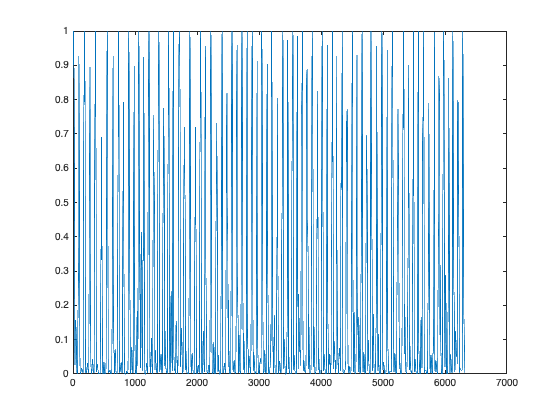

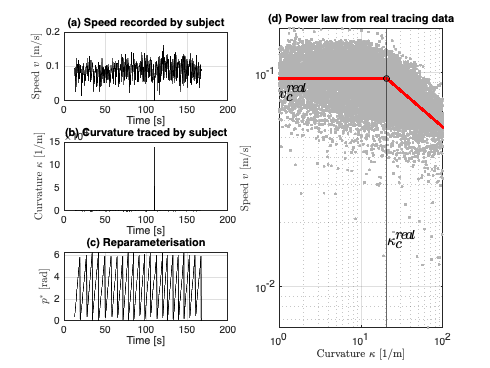

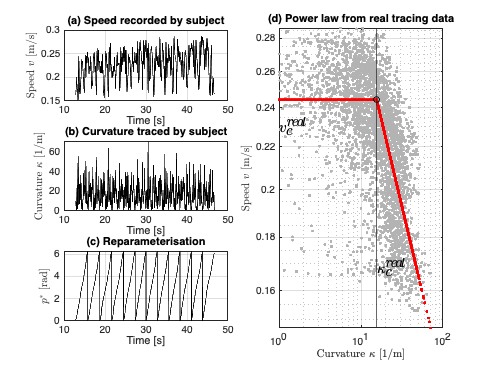

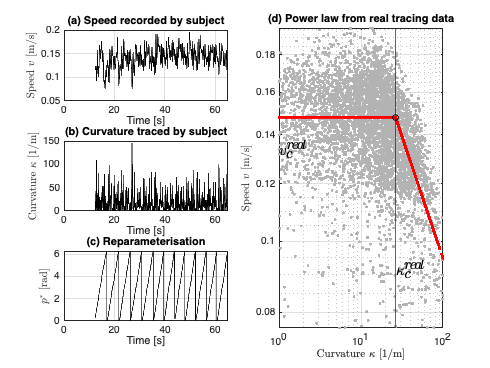

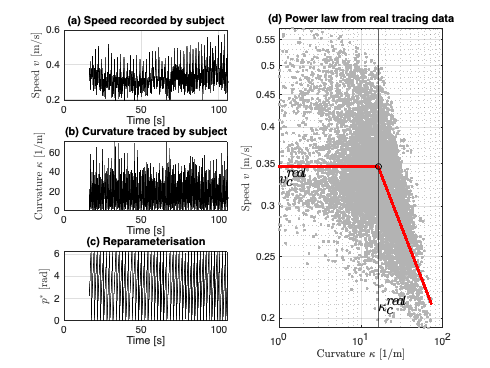

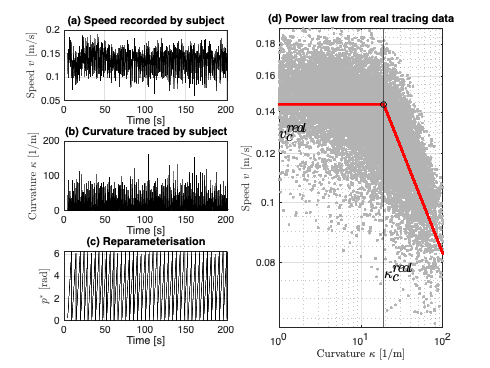

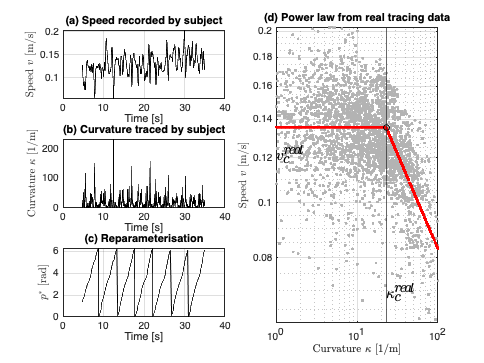

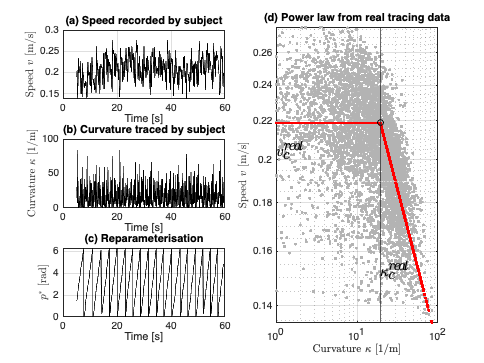

    % PAY ATTENTION TO LABELS and LEGENDS and UNITS
        h_subject_fig2_real_power_law = figure;

        subplot(3,2,1);

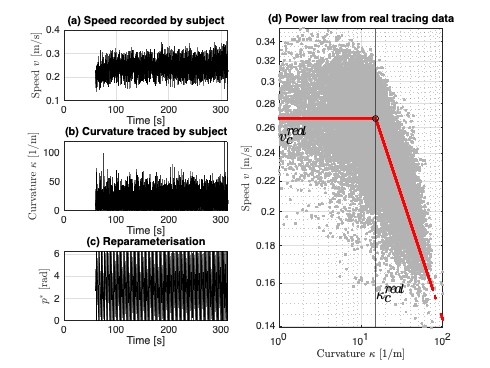

        % Zago filtered speed
            plot(time_zago(range_power_law), speed_zago(range_power_law),'k'); grid on, hold on
            ylabel('Speed $v$ [m/s]','Interpreter','latex'); xlabel('Time [s]'); %xlim([3 80]) %xlim([1 30])
            title('(a) Speed recorded by subject');

        subplot(3,2,3);
        % Zago filtered curvature
            plot(time_zago(range_power_law), curvature_zago(range_power_law),'k'); %ylim([0 100])
            ylabel('Curvature $\kappa$ [1/m]','Interpreter','latex'); xlabel('Time [s]'); %xlim([3 80]) %ylim ([0 50]), 
            title('(b) Curvature traced by subject')
        
        subplot(3,2,[2 4 6]);
        % Log speed vs Log curvature plot, Real data (grey), 
            loglog(curvature_zago(range_power_law), speed_zago(range_power_law), '.', 'Color', [.7 .7 .7]); grid on; hold on;
            loglog (curvature_zago(range_power_law), 10.^Fitting(log10(curvature_zago(range_power_law))), '.r');       
            loglog(VK_par(2), VK_par(1), 'ko')
            text(VK_par(2), min(speed_zago(range_power_law)) + 0.015,'$\kappa_c^{real}$','Interpreter','latex','FontSize',15)
            text(min(curvature_zago(range_power_law)), VK_par(1)-0.015,'$v_c^{real}$','Interpreter','latex','FontSize',15)
            xline(VK_par(2))
            ylabel('Speed $v$ [m/s]','Interpreter','latex'), xlabel('Curvature $\kappa$ [1/m]','Interpreter','latex'),xlim([curvature_threshold 100]); %legend('data','-2/3');
            title('(d) Power law from real tracing data');
        
        subplot(3,2,5);
            plot(time_zago(range_power_law), mod(SET_pstar(range_power_law),2*pi),'k'); grid on, hold on
            xlabel('Time [s]'); ylabel('$p^*$ [rad]','Interpreter','latex'); %xlim([3 80]) %xlim([1 30])
            title('(c) Reparameterisation');
            
        exportgraphics(h_subject_fig2_real_power_law,strcat(pathname, char(subject_fig2_real_power_law),'.pdf'),'BackgroundColor','none');

    
    %% Preparing observations for ELM
    max_C_ss = 50;
    max_mu = 50;

    %% Moving frame geometry
    Z_BUILDER = @(Pt, pstar, GEO) ...
        [ [0 1]*inv( GEO.MF(pstar) ) * (Pt - GEO.C(pstar));
        [0 1] * inv( GEO.MF(pstar) ) * GEO.C_ss(pstar) / max_C_ss;
        0.1*mod(pstar,2*pi);
        ];

    Z_all = [];
    Y_all = [];
    Pt_all = [];
    pstar_all = [];
    for j=1:length(Pt_training)-1
        Pt = Pt_training(:,j);
        Vt = Vt_training(:,j);
        pstar = SET_pstar_training(j);
        pstar = mod(pstar,2*pi);
        Z_all(:,j) = Z_BUILDER( Pt , pstar, GEO);
        Y_all(:,j) = inv(GEO.MF(pstar)) * Vt;
        Pt_all(:,j) = Pt;
        pstar_all(:,j) = pstar;
    end

  


#### Training ELM : Clubbing washout and training

    Ndata = length(Z_all);

    range_train = 1 : Ndata;             %% training range

    range = range_train;    % range for training
    Z_train = Z_all (:, range);
    Y_train = [Y_all(:, range)]; 


#### Storing random starting points from training set

    % generate the four random indices and pick from training set
    randIdcs = randperm(length(Z_train),no_samples);    
    Pt_samples = Pt_all(:,randIdcs);
    pstar_samples = pstar_all(:,randIdcs);

### ELM Training

    ELM.Nx = 100;
    ELM.Nz = min(size(Z_train));
    ELM.Ny = min(size(Y_train));
    rng('default');
    ELM.C = (2.0 * rand(ELM.Nx, ELM.Nz) - 1.0);
    zeta_bias = 0;
    ELM.zeta = zeta_bias * ones(ELM.Nx, 1);
    rho_A = 0.95;
    ELM.A = 0;
    c = 1;
    ELM.Dyn = @(Xt, Zt)radbas(ELM.A * Xt + c * ELM.C * Zt + ELM.zeta);

    % Training phase
    N_train = length(Z_train);
    mean_Z = mean(Z_train, 2);
    std_Z = std(Z_train, [], 2);
    mean_Y = mean(Y_train, 2);
    std_Y = std(Y_train, [], 2);
    Z_train_norm = (Z_train - mean_Z) ./ std_Z;
    Y_train_norm = (Y_train - mean_Y) ./ std_Y;

    options = optimoptions('fmincon', 'Display', 'iter', 'UseParallel', true);
    x_res = fmincon(@(arg_goal)min_lambda_C(arg_goal, ELM, N_train, Z_train_norm, Y_train_norm, ...
        pstar_all(range_train), Pt_all(:,range_train), GEO, Z_BUILDER, sampling_time, mean_Z, std_Z, mean_Y, std_Y), [0.1, 10], ...
        [], [], [], [], [0.01, 1e-5], [10, 800], [], options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    7.565202e-01    0.000e+00    2.554e-03
    1       6    7.565135e-01    0.000e+00    2.553e-03    5.817e-03
    2       9    7.564680e-01    0.000e+00    2.545e-03    4.203e-02
    3      12    7.563705e-01    0.000e+00    2.530e-03    8.705e-02
    4      15    7.560492e-01    0.000e+00    2.477e-03    2.887e-01
    5      18    7.552573e-01    0.000e+00    2.351e-03    7.320e-01
    6      21    7.515642e-01    0.000e+00    1.814e-03    3.949e+00
    7      24    7.477278e-01    0.000e+00    1.320e-03    5.579e+00
    8      28    7.485894e-01    0.000e+00    1.424e-03    1.401e+00
    9      31    7.482215e-01    0.000e+00    1.377e-03    6.167e-01
   10      34    7.483193e-01    0.000e+00    1.389e-03    1.620e-01
   11      37    7.483245e-01    0.000e+00    1.390e-03    3.005e-02
   12      40    7.482556e-01    0.000e+00    1

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    8.571653e-01    0.000e+00    5.746e-04
    1       6    8.571651e-01    0.000e+00    5.747e-04    5.212e-03
    2       9    8.571631e-01    0.000e+00    5.748e-04    3.991e-02
    3      12    8.571593e-01    0.000e+00    5.752e-04    7.370e-02
    4      15    8.571482e-01    0.000e+00    5.761e-04    2.109e-01
    5      18    8.571268e-01    0.000e+00    5.781e-04    4.018e-01
    6      21    8.571144e-01    0.000e+00    5.648e-04    2.285e-01
    7      24    8.570063e-01    0.000e+00    5.744e-04    1.968e+00
    8      27    8.569065e-01    0.000e+00    5.833e-04    1.783e+00
    9      31    8.567578e-01    0.000e+00    5.969e-04    2.603e+00
   10      34    8.567417e-01    0.000e+00    5.984e-04    2.725e-01
   11      37    8.567445e-01    0.000e+00    5.981e-04    6.332e-02
   12      40    8.567402e-01    0.000e+00    5

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    6.066210e-01    0.000e+00    3.358e-04
    1       6    6.066209e-01    0.000e+00    3.358e-04    5.196e-03
    2       9    6.066203e-01    0.000e+00    3.358e-04    3.986e-02
    3      12    6.066192e-01    0.000e+00    3.360e-04    7.335e-02
    4      15    6.066160e-01    0.000e+00    3.365e-04    2.089e-01
    5      18    6.066099e-01    0.000e+00    3.374e-04    3.943e-01
    6      21    6.066068e-01    0.000e+00    3.213e-04    1.945e-01
    7      24    6.065845e-01    0.000e+00    3.246e-04    1.384e+00
    8      27    6.065641e-01    0.000e+00    3.276e-04    1.248e+00
    9      30    6.065237e-01    0.000e+00    3.336e-04    2.433e+00
   10      33    6.065257e-01    0.000e+00    3.332e-04    1.273e-01
   11      36    6.065253e-01    0.000e+00    3.333e-04    3.966e-03
   12      39    6.065231e-01    0.000e+00    3

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    8.192066e-01    0.000e+00    1.509e-03
    1       6    8.192041e-01    0.000e+00    1.509e-03    5.429e-03
    2       9    8.191873e-01    0.000e+00    1.505e-03    4.066e-02
    3      12    8.191536e-01    0.000e+00    1.497e-03    7.842e-02
    4      15    8.190516e-01    0.000e+00    1.475e-03    2.374e-01
    5      18    8.188374e-01    0.000e+00    1.428e-03    5.076e-01
    6      21    8.181780e-01    0.000e+00    1.283e-03    1.674e+00
    7      24    8.168935e-01    0.000e+00    9.964e-04    3.918e+00
    8      28    8.165155e-01    0.000e+00    9.124e-04    1.341e+00
    9      31    8.161327e-01    0.000e+00    8.259e-04    1.509e+00
   10      34    8.160637e-01    0.000e+00    8.102e-04    2.857e-01
   11      37    8.160638e-01    0.000e+00    8.102e-04    5.052e-03
   12      40    8.160580e-01    0.000e+00    8

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    7.725311e-01    0.000e+00    4.696e-04
    1       6    7.725309e-01    0.000e+00    4.696e-04    5.204e-03
    2       9    7.725297e-01    0.000e+00    4.697e-04    3.988e-02
    3      12    7.725273e-01    0.000e+00    4.701e-04    7.352e-02
    4      15    7.725202e-01    0.000e+00    4.710e-04    2.098e-01
    5      18    7.725067e-01    0.000e+00    4.729e-04    3.979e-01
    6      21    7.724993e-01    0.000e+00    4.586e-04    2.110e-01
    7      24    7.724414e-01    0.000e+00    4.664e-04    1.644e+00
    8      27    7.723871e-01    0.000e+00    4.737e-04    1.512e+00
    9      30    7.722458e-01    0.000e+00    4.933e-04    3.822e+00
   10      33    7.722902e-01    0.000e+00    4.869e-04    1.193e+00
   11      36    7.722863e-01    0.000e+00    4.875e-04    1.001e-01
   12      39    7.722848e-01    0.000e+00    4

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    6.639914e-01    0.000e+00    1.851e-04
    1       6    6.639914e-01    0.000e+00    1.850e-04    5.191e-03
    2       9    6.639913e-01    0.000e+00    1.850e-04    3.984e-02
    3      12    6.639910e-01    0.000e+00    1.850e-04    7.325e-02
    4      15    6.639904e-01    0.000e+00    1.850e-04    2.083e-01
    5      18    6.639892e-01    0.000e+00    1.850e-04    3.921e-01
    6      21    6.639885e-01    0.000e+00    1.670e-04    1.841e-01
    7      24    6.639884e-01    0.000e+00    1.670e-04    3.302e-02
    8      27    6.639871e-01    0.000e+00    1.670e-04    3.199e-01
    9      30    6.639825e-01    0.000e+00    1.669e-04    1.100e+00
   10      33    6.639561e-01    0.000e+00    1.666e-04    6.354e+00
   11      37    6.639536e-01    0.000e+00    1.665e-04    5.934e-01
   12      41    6.639529e-01    0.000e+00    1

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    5.515293e-01    0.000e+00    6.411e-04
    1       6    5.515290e-01    0.000e+00    6.411e-04    5.219e-03
    2       9    5.515264e-01    0.000e+00    6.413e-04    3.993e-02
    3      12    5.515216e-01    0.000e+00    6.417e-04    7.384e-02
    4      15    5.515075e-01    0.000e+00    6.427e-04    2.116e-01
    5      18    5.514802e-01    0.000e+00    5.948e-04    4.048e-01
    6      21    5.514635e-01    0.000e+00    6.320e-04    2.418e-01
    7      24    5.513065e-01    0.000e+00    6.428e-04    2.254e+00
    8      27    5.511673e-01    0.000e+00    6.526e-04    1.964e+00
    9      31    5.509967e-01    0.000e+00    6.646e-04    2.368e+00
   10      34    5.509644e-01    0.000e+00    6.671e-04    4.368e-01
   11      37    5.509726e-01    0.000e+00    6.665e-04    1.214e-01
   12      40    5.509700e-01    0.000e+00    6

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.482058e+00    0.000e+00    1.213e-02
    1       6    1.481911e+00    0.000e+00    1.209e-02    1.317e-02
    2       9    1.481119e+00    0.000e+00    1.198e-02    7.285e-02
    3      12    1.478163e+00    0.000e+00    1.160e-02    2.742e-01
    4      15    1.463731e+00    0.000e+00    9.876e-03    1.486e+00
    5      18    1.432717e+00    0.000e+00    6.916e-03    4.131e+00
    6      21    1.386281e+00    0.000e+00    3.993e-03    9.817e+00
    7      24    1.360876e+00    0.000e+00    2.892e-03    8.294e+00
    8      29    1.363788e+00    0.000e+00    3.004e-03    1.092e+00
    9      33    1.362256e+00    0.000e+00    2.945e-03    5.680e-01
   10      36    1.361364e+00    0.000e+00    2.910e-03    3.323e-01
   11      39    1.361249e+00    0.000e+00    2.906e-03    5.675e-02
   12      42    1.359408e+00    0.000e+00    2

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    9.835384e-01    0.000e+00    1.576e-04
    1       6    9.835384e-01    0.000e+00    1.576e-04    5.197e-03
    2       9    9.835381e-01    0.000e+00    1.576e-04    3.986e-02
    3      12    9.835375e-01    0.000e+00    1.575e-04    7.337e-02
    4      15    9.835359e-01    0.000e+00    1.574e-04    2.090e-01
    5      18    9.835329e-01    0.000e+00    1.571e-04    3.946e-01
    6      21    9.835314e-01    0.000e+00    1.570e-04    1.898e-01
    7      24    9.835309e-01    0.000e+00    1.570e-04    6.737e-02
    8      27    9.835253e-01    0.000e+00    1.565e-04    6.864e-01
    9      30    9.835061e-01    0.000e+00    1.548e-04    2.421e+00
   10      33    9.834606e-01    0.000e+00    1.504e-04    5.797e+00
   11      37    9.834667e-01    0.000e+00    1.510e-04    7.903e-01
   12      41    9.834636e-01    0.000e+00    1

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.397925e+00    0.000e+00    1.224e-03
    1       6    1.397923e+00    0.000e+00    1.224e-03    5.353e-03
    2       9    1.397912e+00    0.000e+00    1.222e-03    4.040e-02
    3      12    1.397890e+00    0.000e+00    1.219e-03    7.677e-02
    4      15    1.397823e+00    0.000e+00    1.208e-03    2.280e-01
    5      18    1.397686e+00    0.000e+00    1.186e-03    4.693e-01
    6      21    1.397295e+00    0.000e+00    1.123e-03    1.394e+00
    7      24    1.396491e+00    0.000e+00    9.973e-04    3.119e+00
    8      28    1.396043e+00    0.000e+00    9.286e-04    1.910e+00
    9      31    1.395949e+00    0.000e+00    9.143e-04    4.143e-01
   10      34    1.395721e+00    0.000e+00    8.798e-04    1.027e+00
   11      37    1.395566e+00    0.000e+00    8.565e-04    7.141e-01
   12      40    1.395568e+00    0.000e+00    8

    ridgeLambda = x_res(2);
    c = x_res(1);
    ELM.C =  ELM.C * c;
    c_opt = c;

    disp(ridgeLambda);disp(c);

  118.4088

    1.2297



    0.5238

    4.9581



   1.0004e-05

    9.9478



   21.6116

    5.4745



    0.0195

    5.0236



    0.1534

    4.6716



    0.5541

    4.8267



  799.9982

    1.6256



   21.6546

    4.2689



   33.1263

    3.9354



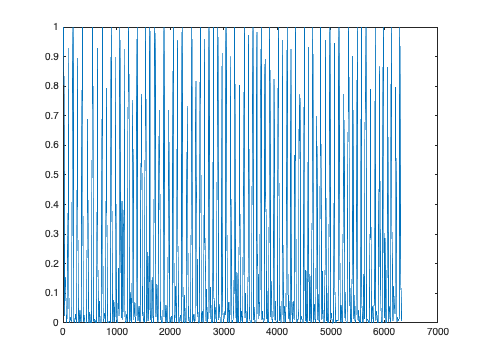

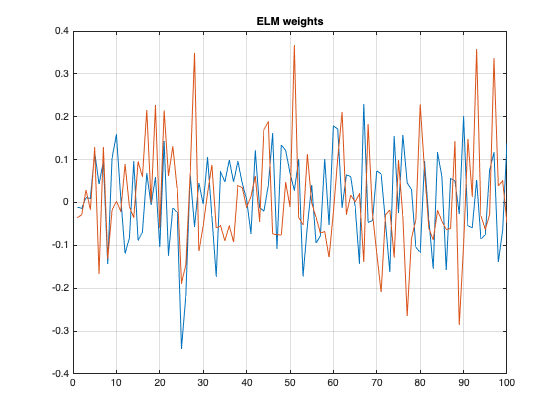

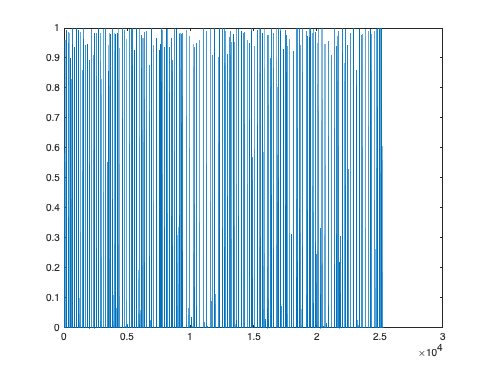

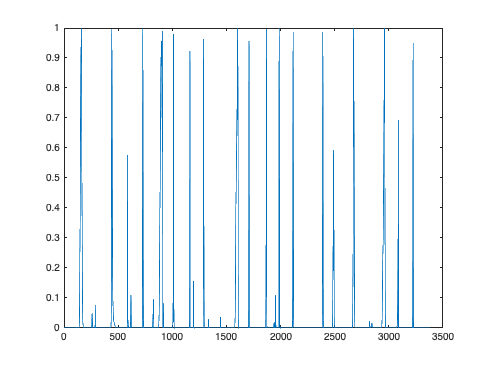

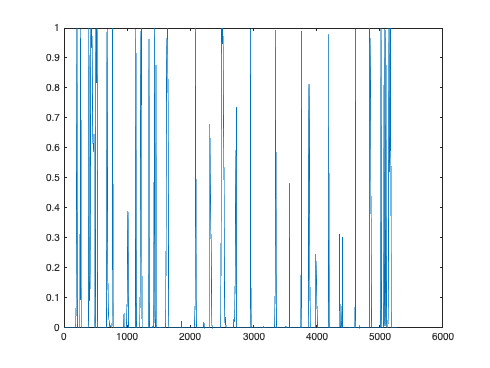

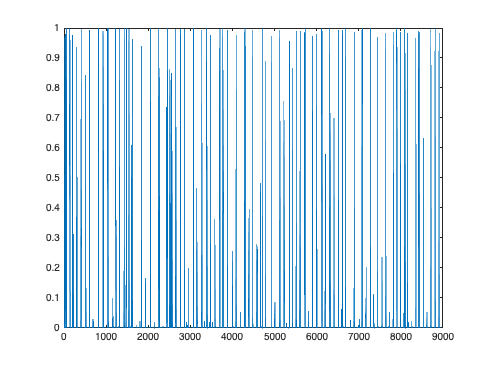

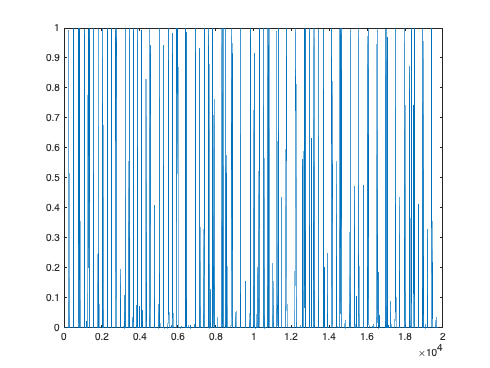

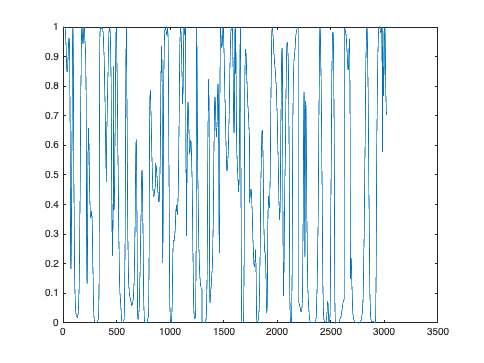

    % Xt contains the last value of the washout set
    j = 1;
    Xt = zeros(ELM.Nx, 1);
    X_train = zeros(ELM.Nx, N_train);
    ELM.Dyn = @(Xt, Zt)radbas(ELM.A * Xt + ELM.C * Zt + ELM.zeta);
    for Zt = Z_train_norm
        Xt = ELM.Dyn(Xt, Zt);
        X_train(:, j) = Xt;
        j = j + 1;
    end
    figure;plot(X_train(1, :));

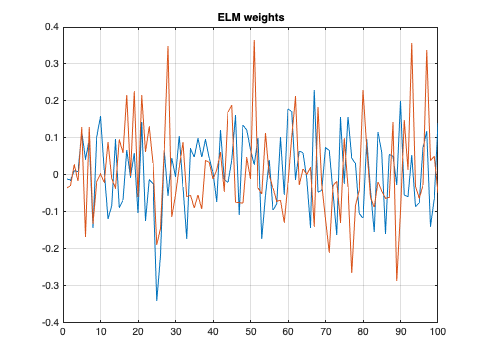

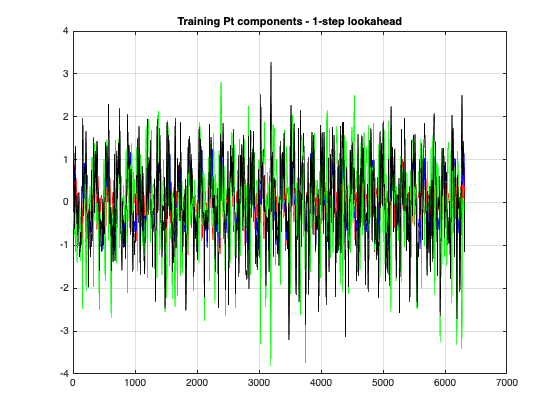

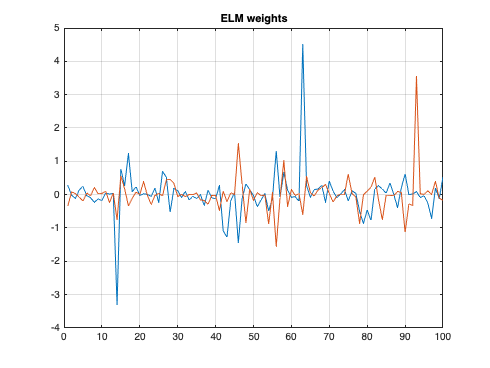

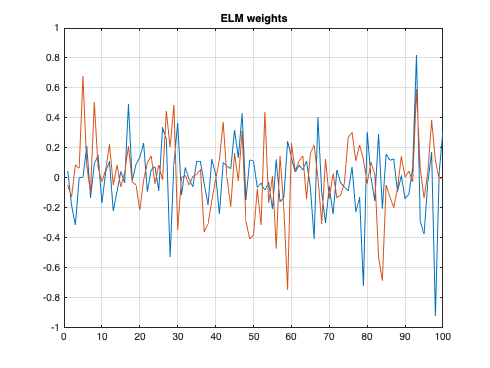

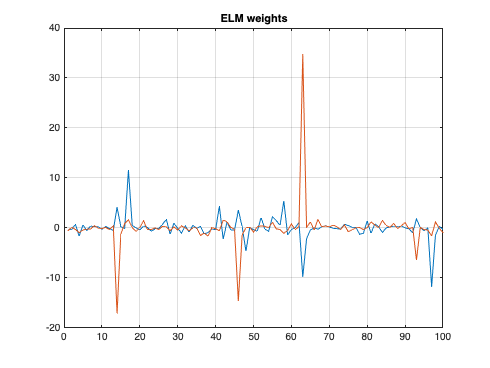

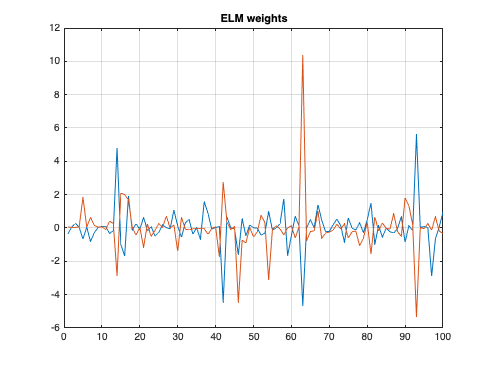

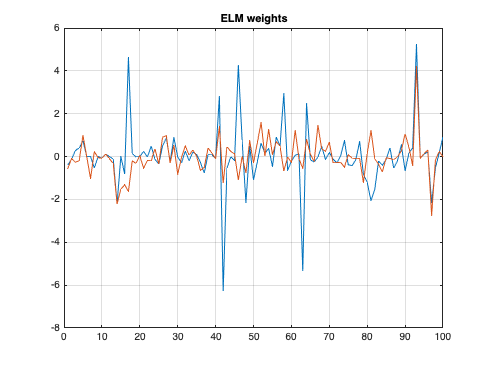

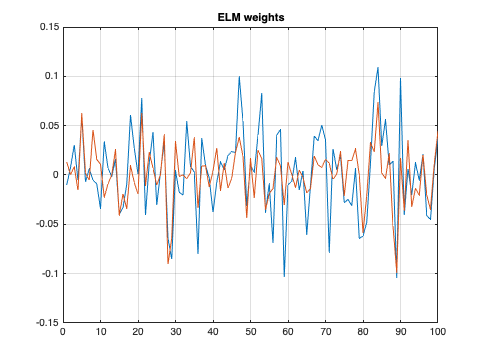


    ELM.W4 = (X_train * X_train' + ridgeLambda * eye(ELM.Nx)) \ (X_train * Y_train_norm');
    ELM.b = mean(Y_train_norm, 2) - ELM.W4' * mean(X_train, 2);
    % definition of 'Eval' function
    ELM.Eval = @(Xt) ELM.W4' * Xt + ELM.b;

    figure;
    plot(ELM.W4);

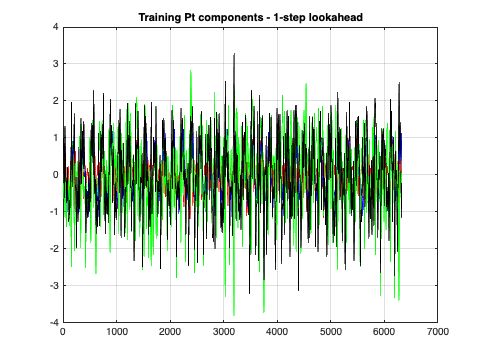

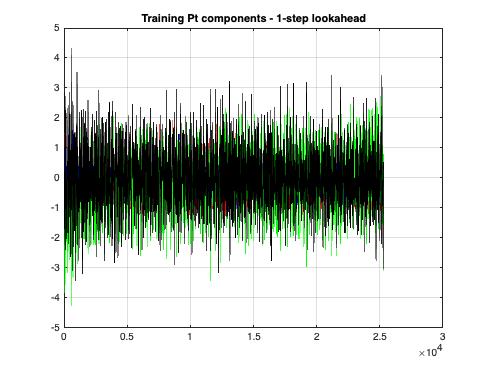

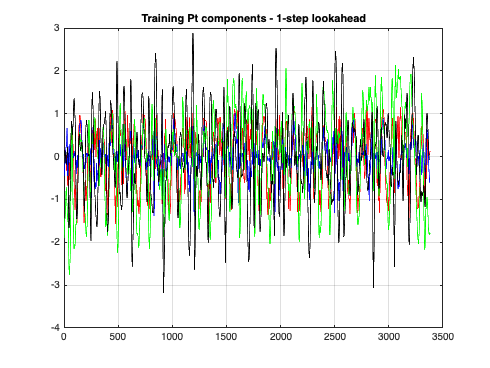

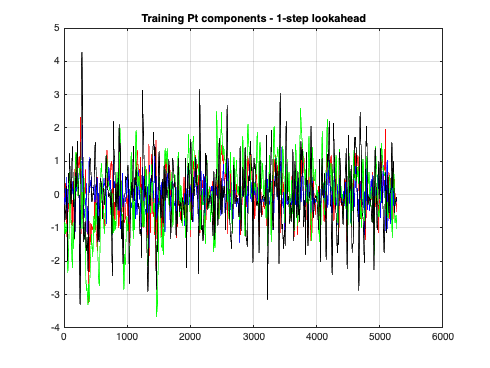

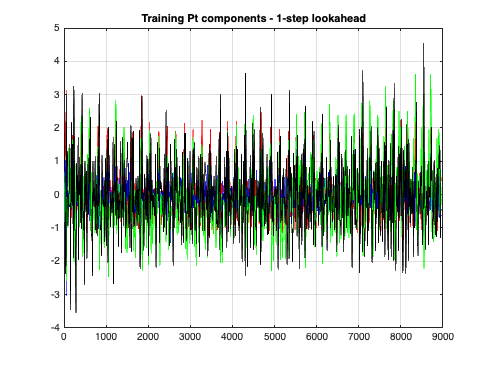

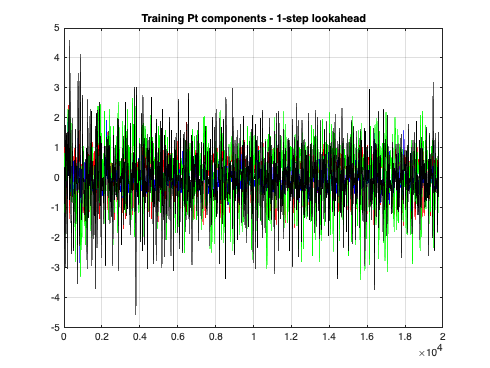

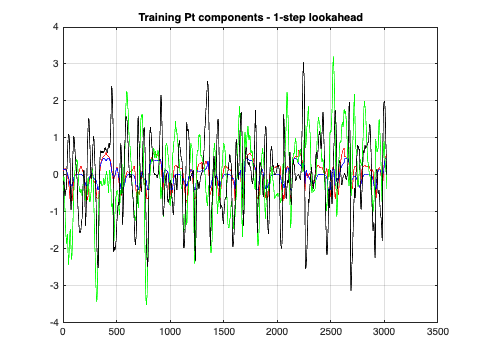

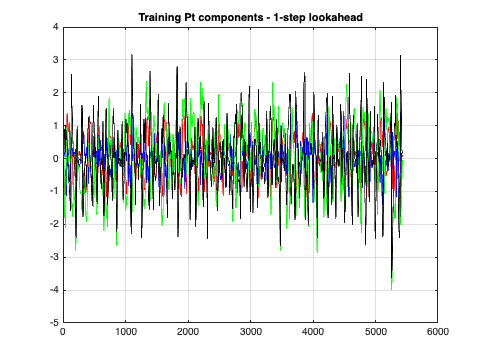

    grid on;
    title('ELM weights');

    Y_train_hat = ELM.Eval(X_train); %Y_train_hat = ELM.W4' * X_train(:, :) + ELM.b;
    figure;
    plot(Y_train_hat(1, :)', 'r');

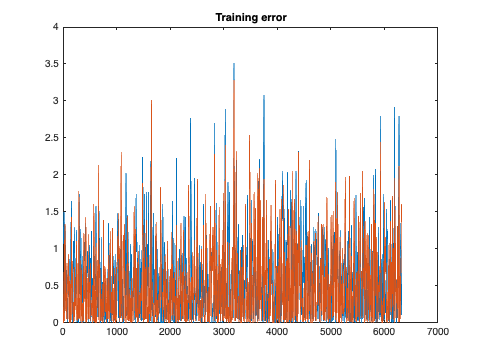

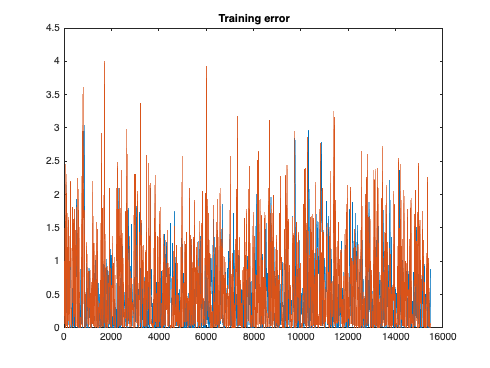

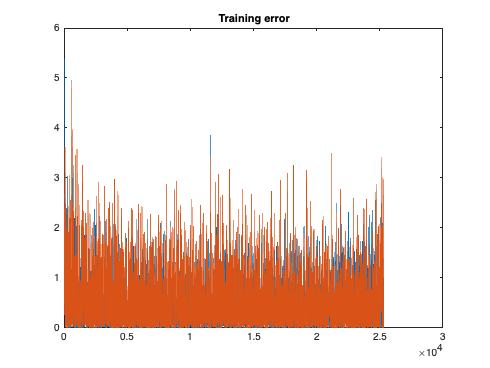

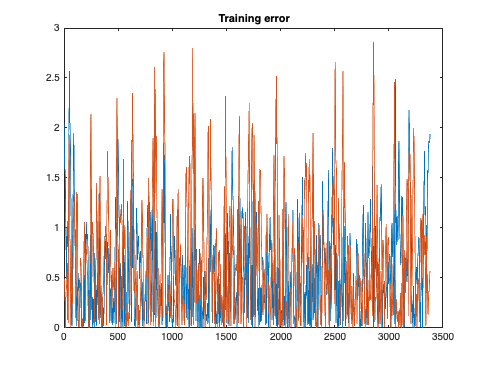

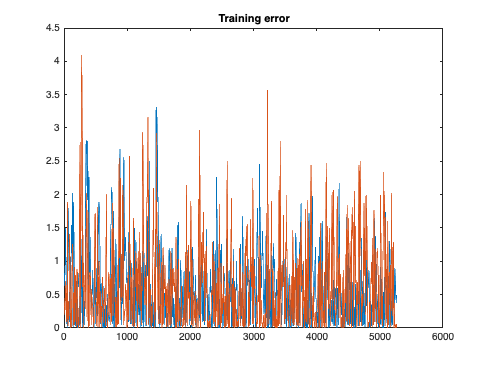

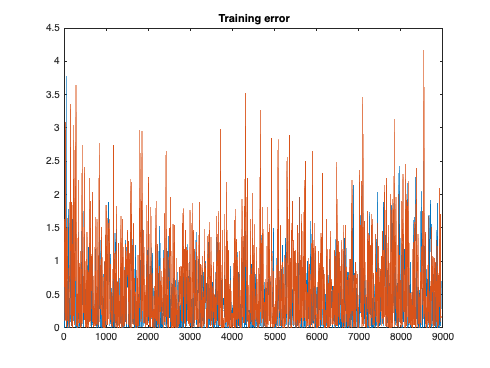

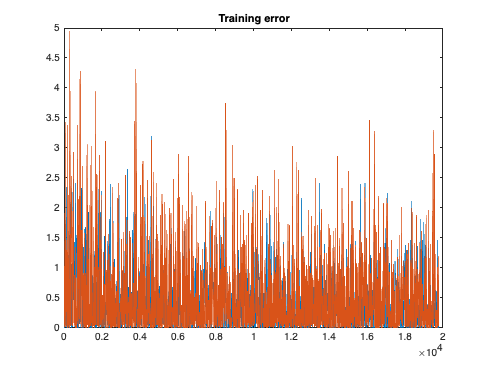

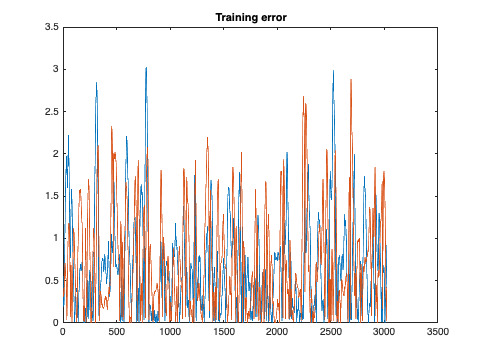

    hold on;
    grid on;
    plot(Y_train_hat(2, :)', 'b');
    hold on;
    grid on;
    plot(Y_train_norm(1, :)', 'g');
    hold on;
    grid on;
    plot(Y_train_norm(2, :)', 'k');
    title('Training Pt components - 1-step lookahead');

    figure;
    plot(abs(Y_train_hat(1,:) - Y_train_norm(1,:)));

    hold on;
    plot(abs(Y_train_hat(2,:) - Y_train_norm(2,:)));
    title('Training error');

    Xt = X_train(:, end);
    X_train_end = X_train(:, end);


### Defining ELM ID for saving this training

    Pt_train = Pt_training;
    Vt_train = Vt_training;
    Pt_end = Pt_train(:,end);

    VK_real = VK_par;
    VK_CI_real = VK_CI;
    
    %% Saving the ELM, real power-law characteristics
    save(strcat(pathname, char(subject_elm_filename)));
    disp('Elapsed time is')

Elapsed time is


Elapsed time is


Elapsed time is


Elapsed time is


Elapsed time is


Elapsed time is


Elapsed time is


Elapsed time is


Elapsed time is


Elapsed time is


    toc

Elapsed time is 331.441252 seconds.


Elapsed time is 560.475049 seconds.


Elapsed time is 1049.211754 seconds.


Elapsed time is 1209.611773 seconds.


Elapsed time is 2070.450177 seconds.


Elapsed time is 2172.193530 seconds.


Elapsed time is 2428.431469 seconds.


Elapsed time is 2573.458974 seconds.


Elapsed time is 2799.618323 seconds.


Elapsed time is 2952.197123 seconds.


end